clc
close all
clear all
cla
fprintf(' Data loading...\n');

 Data loading...


% load gt
rootfolder = '../';
currentfolder = 'tartanair_toy_exp_50_0.5/'

currentfolder = 'tartanair_toy_exp_50_0.5/'

index = 0

index = 0

index_s = int2str(index)

index_s = '0'

V1 = pcread(append(rootfolder,currentfolder,index_s,'/0normal.pcd'))';
V2 = pcread(append(rootfolder,currentfolder,index_s,'/1normal.pcd'))';
V3 = pcread(append(rootfolder,currentfolder,index_s,'/2normal.pcd'))';
V4 = pcread(append(rootfolder,currentfolder,index_s,'/3normal.pcd'))';

V10 = pcread(append(rootfolder,'demo_data/result_cvo190.pcd'))';
V20 = pcread(append(rootfolder,'demo_data/result_cvo210.pcd'))';
V30 = pcread(append(rootfolder,'demo_data/result_cvo230.pcd'))';
V40 = pcread(append(rootfolder,'demo_data/result_cvo250.pcd'))';

V = {V1,V2,V3,V4}';
V0 = {V10,V20,V30,V40}';
figure(1)
colormap = {[255,0,0],[0,255,0],[0,0,255],[255,165,0]};
Point_inlier = {}


Point_inlier =

  0×0 empty cell array



Point_outlier = {}


Point_outlier =

  0×0 empty cell array



Point_original = {}


Point_original =

  0×0 empty cell array



gtfilename = append(rootfolder,currentfolder,index_s,'/gt_poses.txt')

gtfilename = '../tartanair_toy_exp_50_0.5/0/gt_poses.txt'

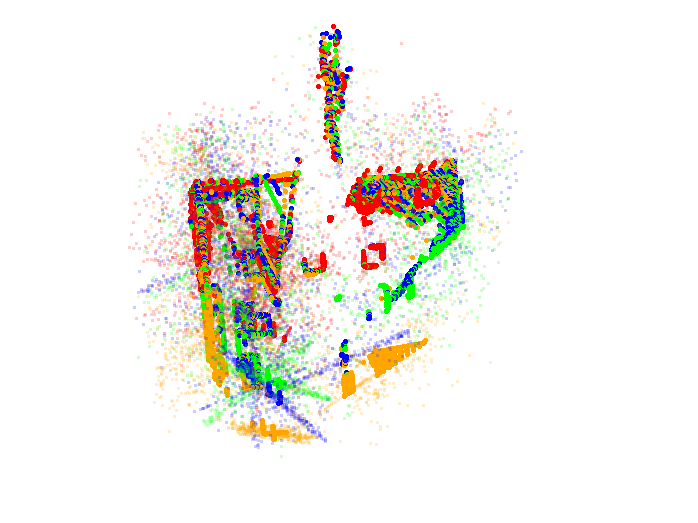

A = readmatrix(gtfilename);
Tcvo = {reshape(A(1,:),[4,4])',reshape(A(2,:),[4,4])',reshape(A(3,:),[4,4])',reshape(A(4,:),[4,4])'}';
for i=1:4
    Tcvo{i} = inv(Tcvo{i});
end
for i=1:4
    T = Tcvo{i};
    locaiton = V{i}.Location;
    locaiton = bsxfun(@plus,T(1:3,1:3) *V{i}.Location',T(1:3,4))';
%     size(locaiton)
    color =  V{i}.Color;
    [h w] = size(locaiton);
    inlier = zeros(h,w);
    outlier =  zeros(h,w);
    for j=1:h
        if color(j,:) == [255 0 0]
            inlier(j,:) = locaiton(j,:);
        else
            outlier(j,:) = locaiton(j,:);
        end

    end
    Point_inlier{i} = inlier;
    Point_outlier{i} = outlier;
    Point_original{i} = V0{i}.Location;
   
end
figure(1)
for i=1:4

    scatter3(Point_original{i}(:,1),Point_original{i}(:,2),Point_original{i}(:,3),5,colormap{i}/255,'filled','MarkerFaceAlpha',1)
    hold on 
    scatter3(Point_outlier{i}(:,1),Point_outlier{i}(:,2),Point_outlier{i}(:,3),2,colormap{i}/255,'filled','MarkerFaceAlpha',0.2)
    axis equal
    grid off 
    axis off
   

end
axis([-50 50 -50 50 -50 50 ])
set(gca,'LooseInset',get(gca,'TightInset'));
 pos = get(gca, 'Position');
    pos(1) = 0.055;
    pos(3) = 0.9;
    set(gca, 'Position', pos)
xlim([-6.4 15.2])
ylim([-9.9 11.7])
zlim([-5.6 16.0])
view([-16.5 7.3])
hold off

## Before


cla
fprintf(' Data loading...\n');

 Data loading...


% load gt
rootfolder = '../../exp/tartanair_full_semantic/';
currentfolder = 'tartanair_toy_exp_50_0.5/'

currentfolder = 'tartanair_toy_exp_50_0.5/'

index = 2

index = 2

index_s = int2str(index)

index_s = '2'


figure(1)
colormap = {[255,0,0],[0,255,0],[0,0,255],[255,165,0]};

gtfilename = append(rootfolder,currentfolder,index_s,'/gt_poses.txt')

gtfilename = '../../exp/tartanair_full_semantic/tartanair_toy_exp_50_0.5/2/gt_poses.txt'

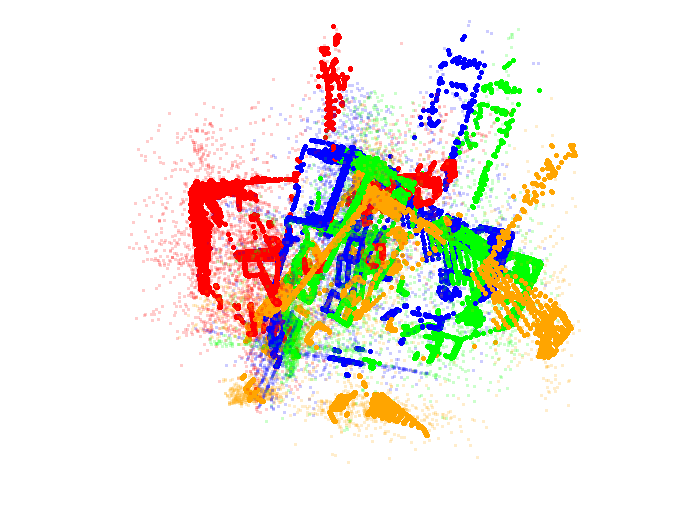

A = readmatrix(gtfilename);
Tcvo = {reshape(A(1,:),[4,4])',reshape(A(2,:),[4,4])',reshape(A(3,:),[4,4])',reshape(A(4,:),[4,4])'}';
% for i=1:4
%     Tcvo{i} = inv(Tcvo{i});
% end
Point_outlier_cur= {};
Point_original_cur = {};
for i=1:4
    T = Tcvo{i};
    location = Point_outlier{i};
    locaiton = bsxfun(@plus,T(1:3,1:3) *location',T(1:3,4))';
%     size(locaiton)
   
    [h w] = size(locaiton);
    inlier = zeros(h,w);
    outlier =  zeros(h,w);
    Point_original_cur{i} = bsxfun(@plus,T(1:3,1:3) * Point_original{i}',T(1:3,4))';
    Point_outlier_cur{i} = locaiton;
   
end
figure(1)
for i=1:4

    scatter3(Point_original_cur{i}(:,1),Point_original_cur{i}(:,2),Point_original_cur{i}(:,3),5,colormap{i}/255,'filled','MarkerFaceAlpha',1)
    hold on 
    scatter3(Point_outlier_cur{i}(:,1),Point_outlier_cur{i}(:,2),Point_outlier_cur{i}(:,3),2,colormap{i}/255,'filled','MarkerFaceAlpha',0.2)
    axis equal
    grid off 
    axis off
   

end
axis([-50 50 -50 50 -50 50 ])
set(gca,'LooseInset',get(gca,'TightInset'));
 pos = get(gca, 'Position');
    pos(1) = 0.055;
    pos(3) = 0.9;
    set(gca, 'Position', pos)
xlim([-6.4 15.2])
ylim([-9.9 11.7])
zlim([-5.6 16.0])
view([-16.5 7.3])
hold off

## Cvo result


cla
fprintf(' Data loading...\n');

 Data loading...


% load gt
rootfolder = '../../exp/tartanair_full_semantic/';
currentfolder = 'tartanair_toy_exp_50_0.5/'

currentfolder = 'tartanair_toy_exp_50_0.5/'

index = 2

index = 2

index_s = int2str(index)

index_s = '2'


figure(1)
colormap = {[255,0,0],[0,255,0],[0,0,255],[255,165,0]};

gtfilename = append(rootfolder,currentfolder,index_s,'/gt_poses.txt')

gtfilename = '../../exp/tartanair_full_semantic/tartanair_toy_exp_50_0.5/2/gt_poses.txt'

A = readmatrix(gtfilename);
Tgtr = {reshape(A(1,:),[4,4])',reshape(A(2,:),[4,4])',reshape(A(3,:),[4,4])',reshape(A(4,:),[4,4])'}';
gtfilename = append(rootfolder,currentfolder,index_s,'/rkhs_intencity_result.txt')

gtfilename = '../../exp/tartanair_full_semantic/tartanair_toy_exp_50_0.5/2/rkhs_intencity_result.txt'

A = readmatrix(gtfilename);
Tcvo = {reshape(A(1,:),[4,4])',reshape(A(2,:),[4,4])',reshape(A(3,:),[4,4])',reshape(A(4,:),[4,4])'}';
% for i=1:4
%     Tcvo{i} = inv(Tcvo{i});
% end
Point_outlier_cur= {};
Point_original_cur = {};
for i=1:4
    T = Tgtr{i};
    T_c = Tcvo{i}
    location = Point_outlier{i};
    location = bsxfun(@plus,T(1:3,1:3) *location',T(1:3,4))';
    location = bsxfun(@plus,T_c(1:3,1:3) *location',T_c(1:3,4))';
%     size(locaiton)
     Point_outlier_cur{i} = location;
    [h w] = size(location);
    inlier = zeros(h,w);
    outlier =  zeros(h,w);
    Point_original_cur{i} = bsxfun(@plus,T(1:3,1:3) * Point_original{i}',T(1:3,4))';
    Point_original_cur{i} = bsxfun(@plus,T_c(1:3,1:3) * Point_original_cur{i}',T_c(1:3,4))';
  

   
end

T_c =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


T_c =     0.6750    0.5883   -0.4453   -1.0645
   -0.4194    0.8025    0.4244    0.7598
    0.6070   -0.0997    0.7884   -1.6545
         0         0         0    1.0000


T_c =     0.6660    0.6401   -0.3830   -1.3694
   -0.5267    0.7672    0.3661    0.1394
    0.5282   -0.0421    0.8481   -1.7438
         0         0         0    1.0000


T_c =     0.8237    0.2854   -0.4900   -1.9071
    0.0392    0.8334    0.5513   -0.5398
    0.5657   -0.4733    0.6753   -0.7156
         0         0         0    1.0000


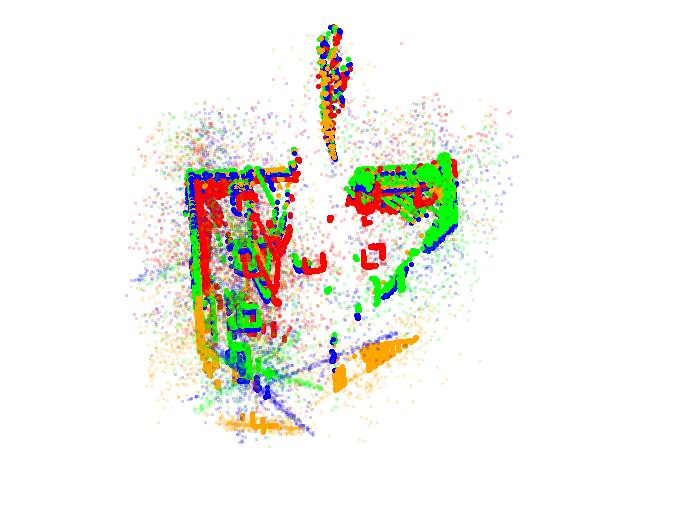

figure(1)
for i=1:4

    scatter3(Point_original_cur{i}(:,1),Point_original_cur{i}(:,2),Point_original_cur{i}(:,3),5,colormap{i}/255,'filled','MarkerFaceAlpha',1)
    hold on 
    scatter3(Point_outlier_cur{i}(:,1),Point_outlier_cur{i}(:,2),Point_outlier_cur{i}(:,3),2,colormap{i}/255,'filled','MarkerFaceAlpha',0.2)
    axis equal
    grid off 
    axis off
   

end
axis([-50 50 -50 50 -50 50 ])
set(gca,'LooseInset',get(gca,'TightInset'));
 pos = get(gca, 'Position');
    pos(1) = 0.055;
    pos(3) = 0.9;
    set(gca, 'Position', pos)
xlim([-6.4 15.2])
ylim([-9.9 11.7])
zlim([-5.6 16.0])
view([-16.5 7.3])
hold off

## cvo semantics


cla
fprintf(' Data loading...\n');

 Data loading...


% load gt
rootfolder = '../../exp/tartanair_full_semantic/';
currentfolder = 'tartanair_toy_exp_50_0.5/'

currentfolder = 'tartanair_toy_exp_50_0.5/'

index = 2

index = 2

index_s = int2str(index)

index_s = '2'


figure(1)
colormap = {[255,0,0],[0,255,0],[0,0,255],[255,165,0]};

gtfilename = append(rootfolder,currentfolder,index_s,'/gt_poses.txt')

gtfilename = '../../exp/tartanair_full_semantic/tartanair_toy_exp_50_0.5/2/gt_poses.txt'

A = readmatrix(gtfilename);
Tgtr = {reshape(A(1,:),[4,4])',reshape(A(2,:),[4,4])',reshape(A(3,:),[4,4])',reshape(A(4,:),[4,4])'}';
gtfilename = append(rootfolder,currentfolder,index_s,'/rkhs_results.txt')

gtfilename = '../../exp/tartanair_full_semantic/tartanair_toy_exp_50_0.5/2/rkhs_results.txt'

A = readmatrix(gtfilename);
Tcvo = {reshape(A(1,:),[4,4])',reshape(A(2,:),[4,4])',reshape(A(3,:),[4,4])',reshape(A(4,:),[4,4])'}';
% for i=1:4
%     Tcvo{i} = inv(Tcvo{i});
% end
Point_outlier_cur= {};
Point_original_cur = {};
for i=1:4
    T = Tgtr{i};
    T_c = Tcvo{i}
    location = Point_outlier{i};
    location = bsxfun(@plus,T(1:3,1:3) *location',T(1:3,4))';
    location = bsxfun(@plus,T_c(1:3,1:3) *location',T_c(1:3,4))';
%     size(locaiton)
     Point_outlier_cur{i} = location;
    [h w] = size(location);
    inlier = zeros(h,w);
    outlier =  zeros(h,w);
    Point_original_cur{i} = bsxfun(@plus,T(1:3,1:3) * Point_original{i}',T(1:3,4))';
    Point_original_cur{i} = bsxfun(@plus,T_c(1:3,1:3) * Point_original_cur{i}',T_c(1:3,4))';
  

   
end

T_c =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


T_c =     0.6903    0.5544   -0.4649   -1.0213
   -0.3880    0.8260    0.4089    0.6168
    0.6107   -0.1018    0.7853   -1.5600
         0         0         0    1.0000


T_c =     0.6845    0.6036   -0.4089   -1.1717
   -0.4916    0.7963    0.3526   -0.0952
    0.5384   -0.0403    0.8417   -1.6941
         0         0         0    1.0000


T_c =     0.8240    0.2539   -0.5066   -1.8332
    0.0710    0.8407    0.5368   -0.7400
    0.5622   -0.4783    0.6747   -0.6153
         0         0         0    1.0000


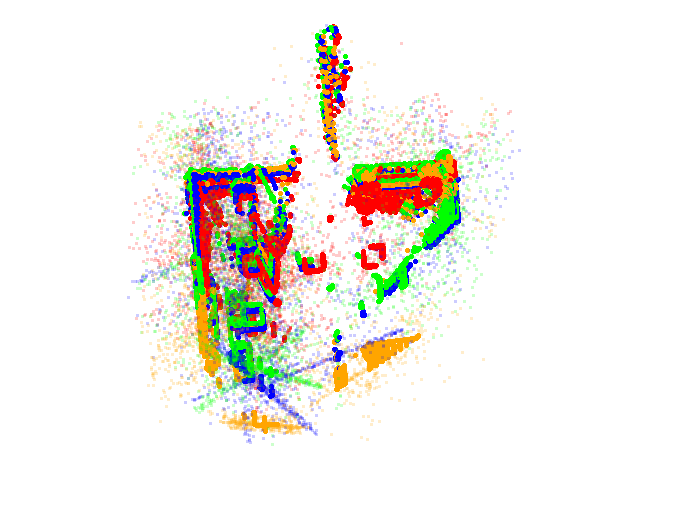

figure(1)
for i=1:4

    scatter3(Point_original_cur{i}(:,1),Point_original_cur{i}(:,2),Point_original_cur{i}(:,3),5,colormap{i}/255,'filled','MarkerFaceAlpha',1)
    hold on 
    scatter3(Point_outlier_cur{i}(:,1),Point_outlier_cur{i}(:,2),Point_outlier_cur{i}(:,3),2,colormap{i}/255,'filled','MarkerFaceAlpha',0.2)
    axis equal
    grid off 
    axis off
   

end
axis([-50 50 -50 50 -50 50 ])
set(gca,'LooseInset',get(gca,'TightInset'));
 pos = get(gca, 'Position');
    pos(1) = 0.055;
    pos(3) = 0.9;
    set(gca, 'Position', pos)
xlim([-6.4 15.2])
ylim([-9.9 11.7])
zlim([-5.6 16.0])
view([-16.5 7.3])
hold off

## jrmpc

cla
fprintf(' Data loading...\n');

 Data loading...


% load gt
rootfolder = '../../exp/tartanair_full_semantic/';
currentfolder = 'tartanair_toy_exp_50_0.5/'

currentfolder = 'tartanair_toy_exp_50_0.5/'

index = 2

index = 2

index_s = int2str(index)

index_s = '2'


figure(1)
colormap = {[255,0,0],[0,255,0],[0,0,255],[255,165,0]};

gtfilename = append(rootfolder,currentfolder,index_s,'/gt_poses.txt')

gtfilename = '../../exp/tartanair_full_semantic/tartanair_toy_exp_50_0.5/2/gt_poses.txt'

A = readmatrix(gtfilename);
Tgtr = {reshape(A(1,:),[4,4])',reshape(A(2,:),[4,4])',reshape(A(3,:),[4,4])',reshape(A(4,:),[4,4])'}';
gtfilename = append(rootfolder,currentfolder,index_s,'/jrmpc.txt')

gtfilename = '../../exp/tartanair_full_semantic/tartanair_toy_exp_50_0.5/2/jrmpc.txt'

A = readmatrix(gtfilename);
Tcvo = {reshape(A(1,:),[4,4])',reshape(A(2,:),[4,4])',reshape(A(3,:),[4,4])',reshape(A(4,:),[4,4])'}';

for i=1:4
    Tcvo{i} = inv(Tcvo{1}) * Tcvo{i};
end
Point_outlier_cur= {};
Point_original_cur = {};
for i=1:4
    T = Tgtr{i};
    T_c = Tcvo{i}
    location = Point_outlier{i};
    location = bsxfun(@plus,T(1:3,1:3) *location',T(1:3,4))';
    location = bsxfun(@plus,T_c(1:3,1:3) *location',T_c(1:3,4))';
%     size(locaiton)
     Point_outlier_cur{i} = location;
    [h w] = size(location);
    inlier = zeros(h,w);
    outlier =  zeros(h,w);
    Point_original_cur{i} = bsxfun(@plus,T(1:3,1:3) * Point_original{i}',T(1:3,4))';
    Point_original_cur{i} = bsxfun(@plus,T_c(1:3,1:3) * Point_original_cur{i}',T_c(1:3,4))';
  

   
end

T_c =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


T_c =     0.8241    0.0834    0.5603   -8.7013
    0.3931   -0.7963   -0.4597    1.4911
    0.4079    0.5991   -0.6890    9.0864
         0         0         0    1.0000


T_c =     0.7541    0.1593    0.6371   -8.6438
    0.5017   -0.7657   -0.4024    2.1012
    0.4238    0.6231   -0.6574    8.8815
         0         0         0    1.0000


T_c =     0.8318   -0.3750    0.4093   -7.5447
   -0.0747   -0.8062   -0.5869    2.7100
    0.5500    0.4576   -0.6986    8.0266
         0         0         0    1.0000


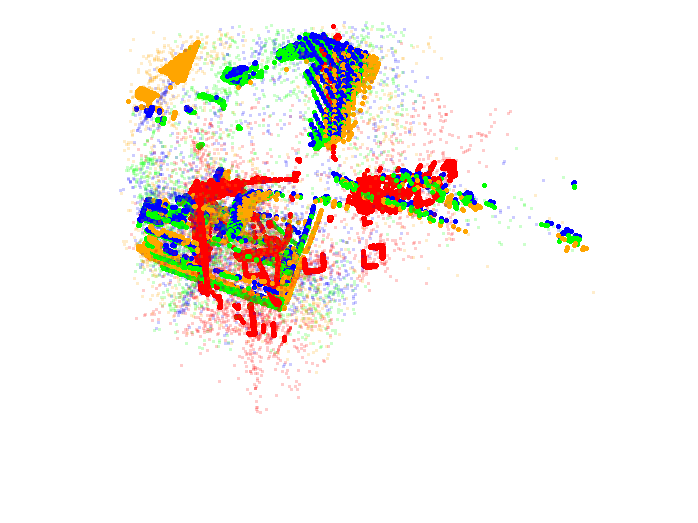

figure(1)
for i=1:4

    scatter3(Point_original_cur{i}(:,1),Point_original_cur{i}(:,2),Point_original_cur{i}(:,3),5,colormap{i}/255,'filled','MarkerFaceAlpha',1)
    hold on 
    scatter3(Point_outlier_cur{i}(:,1),Point_outlier_cur{i}(:,2),Point_outlier_cur{i}(:,3),2,colormap{i}/255,'filled','MarkerFaceAlpha',0.2)
    axis equal
    grid off 
    axis off
   

end
axis([-50 50 -50 50 -50 50 ])
set(gca,'LooseInset',get(gca,'TightInset'));
 pos = get(gca, 'Position');
    pos(1) = 0.055;
    pos(3) = 0.9;
    set(gca, 'Position', pos)
xlim([-6.4 15.2])
ylim([-9.9 11.7])
zlim([-5.6 16.0])
view([-16.5 7.3])
hold off